# Platooning Analysis Confidence

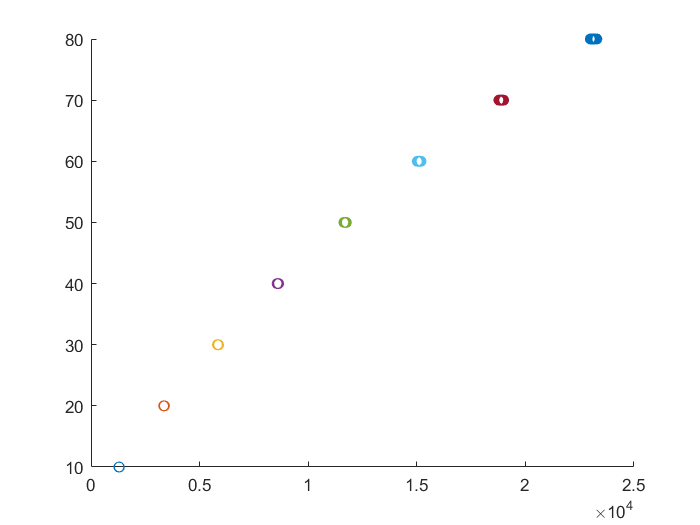

clear, clc, close all

% Creating Confidence intervals for base case and plat case of 20% 4tr 2.5m

% Folder name where results are
Folder_Name{1} = 'PlatoonConfidence';       % 100 trials of base analysis 50k
Folder_Name{2} = 'PlatoonConfidence2';      % 100 trials of base analysis 2mp
Folder_Name{3} = 'PlatoonConfidenceP';      % 100 trials of plat analysis 50k
Folder_Name{4} = 'PlatoonConfidenceP2';     % 30 trials of plat analysis 2m

MuName = {'Mu' 'Mu2' 'MuP' 'MuP2'};
MaxName = {'Max' 'Max2' 'MaxP' 'MaxP2'};
MaxxName = {'Maxx' 'Maxx2' 'MaxxP' 'MaxxP2'};

GoF = [];

for j = 1:length(Folder_Name)
    File_List = GetFileList(Folder_Name{j});
    
    % Read in .mat results variables into a signle OInfo variable
    for i = 1:length(File_List)
        load(['Output/' Folder_Name{j} '/' File_List(i).name])
        OInfo(i) = OutInfo;
        
        % Create matrix of just span lengths
        for k = 1:length(OInfo(i).InfNames)
            SpanLengths(k) = str2num(OInfo(i).InfNames{k}(end-1:end));
        end

    end
    
    clear OutInfo
    ResultsPerRun = 8;
    SpanDiv = 10;
    
    % Step through all output files and put them into Structure Variable
    for i = 1:length(OInfo)
        
        for k = 1:length(unique(OInfo(i).InfNames))-2
            % Get InfName (call it Temp)
            UniqNames = unique(OInfo(i).InfNames,'stable');
            
            Temp = UniqNames{k}; %Fixed 26.5.20
            % Get Span from InfName
            Span = str2num(Temp(end-1:end));
            % Get Action Effect from InfName
            AEx = Temp(1:end-2);
            
            % Average Result
            Res.(MuName{j}).(AEx)(i,Span/SpanDiv) = OInfo(i).Mean(k);
            % Max Type Result
            Res.(MaxName{j}).(AEx)(i,Span/SpanDiv) = OInfo(i).ESIM(k);
            % Max Type 2 Result
            b = sort(OInfo(i).OverMax(:,k),'descend');
            %Res.(MaxxName{j}).(AEx)(i,Span/SpanDiv) = mean(b(1:10))*1.1;
            
            
%             histogram(b,30);
%             histfit(b,30,'lognormal');
%             x_values = 450:700;
%             y_values = pdf(pd,x_values);
%             plot(x_values,y_values);

% UNCOMMENT TO SWITCH TO NEW LOGNORMAL METHOD...
% Basically we used to get the 99% from the ecdf, and now we are getting it
% from a lognormal fit cdf. We've also tried doing the average between the
% 98 and 100th percentile.
            Fit = lognfit(b);
            pd = makedist('lognormal',"mu",Fit(1),"sigma",Fit(2));
            Res.(MaxxName{j}).(AEx)(i,Span/SpanDiv) = icdf(pd,.99)*1.1;
            
            %if j == 1 & i == 1 & k == 1
                 [MaxECDF, MaxECDFRank] = ecdf(b); MaxECDFRank = MaxECDFRank';  MaxECDF(1) = []; MaxECDFRank(1) = [];
%                 figure
%                 hold on
%                 scatter(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),log(MaxECDFRank),7,[0.5 0.5 0.5],'filled','DisplayName','Data');
                 mdl = fitlm(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),log(MaxECDFRank),'linear');
%                 
%                 plot(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),mdl.Fitted,'-','Color',[0.5 0.5 0.5],'DisplayName',['Fitted ' num2str(mdl.Rsquared.Ordinary,3)]);
%     
%                 box on
%                 y1 = ylim;
%                 
%                 text(1,y1(1)+(y1(2)-y1(1))*(j/6),sprintf('R^2:  %.1f%%',mdl.Rsquared.Ordinary*100),"Color",[1 1 1])
%                 
                GoF = [GoF; mdl.Rsquared.Ordinary];
                
            %end 
        end
    end
    
    clear OInfo
    figure
    z = repmat(10:10:80,100,1);
    for i = 1:8
        scatter(Res.Mu.Mp(:,i),z(:,i))
        hold on
        xbar(i) = mean(Res.Mu.Mp(:,i));
        xstd(i) = std(Res.Mu.Mp(:,i));
    end
    % Could also plot Max's instead of Mu's ... not a big def. between Max
    % and Maxx
%     for i = 1:8
%         scatter(Res.Max.Mp(:,i),z(:,i))
%         hold on
%         xbar(i) = mean(Res.Max.Mp(:,i));
%         xstd(i) = std(Res.Max.Mp(:,i));
%     end
end

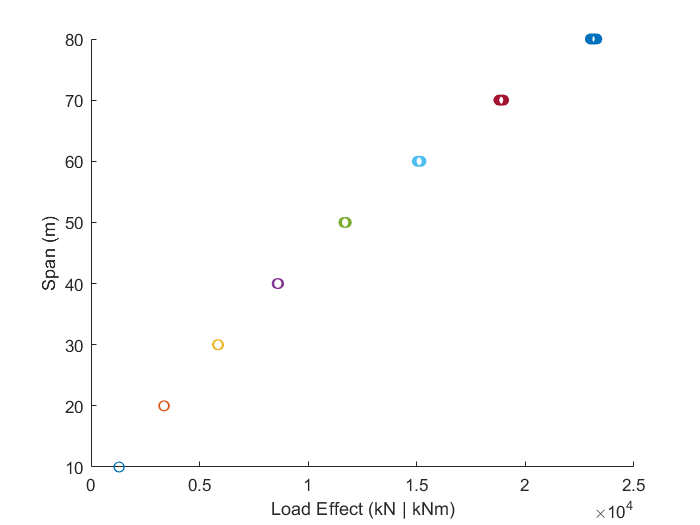

ylabel('Span (m)')
xlabel('Load Effect (kN | kNm)')

AEs = {'V' 'Mp' 'Mn'};

% What we want to do here is divide EACH plat result with ALL base results.
for j = 1:3
    for i = 1:8
        
        % Several different methods here
        % A) divide EACH plat result with ALL base results
        % B) divide EACH plat result with the mean of the base results
        % Can do this while using Max OR Maxx
        RxA = Res.MaxP.(AEs{j})(:,i)'./Res.Max.(AEs{j})(:,i);
        RxB = Res.MaxP.(AEs{j})(:,i)'./mean(Res.Max.(AEs{j})(:,i));
        RxxA = Res.MaxxP.(AEs{j})(:,i)'./Res.Maxx.(AEs{j})(:,i);
        RxxB = Res.MaxxP.(AEs{j})(:,i)'./mean(Res.Maxx.(AEs{j})(:,i));
        Ratio.(AEs{j})(:,i) = RxxB(:);
        
        x = Ratio.(AEs{j})(:,i);
        CI.(AEs{j})(1:2,i) = quantile(x,[.025 .975]);
        Med.(AEs{j})(1:2,i) = quantile(x,0.5);
        
        R2xA = Res.MaxP2.(AEs{j})(:,i)'./Res.Max2.(AEs{j})(:,i);
        R2xB = Res.MaxP2.(AEs{j})(:,i)'./mean(Res.Max2.(AEs{j})(:,i));
        R2xxA = Res.MaxxP2.(AEs{j})(:,i)'./Res.Maxx2.(AEs{j})(:,i);
        R2xxB = Res.MaxxP2.(AEs{j})(:,i)'./mean(Res.Maxx2.(AEs{j})(:,i));
        Ratio2.(AEs{j})(:,i) = R2xxB(:);
        
        x = Ratio2.(AEs{j})(:,i);                   
        CI2.(AEs{j})(1:2,i) = quantile(x,[.025 .975]);
        Med2.(AEs{j})(1:2,i) = quantile(x,0.5);
        
    end
end

Now Plot the results

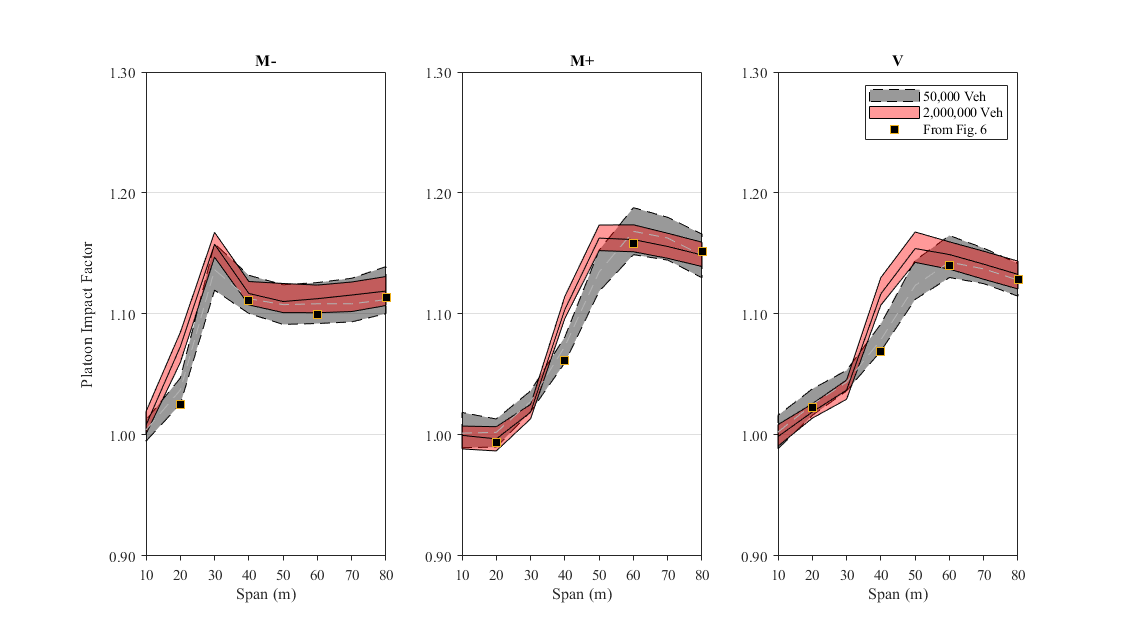

close all

load('Misc\SimPts.mat')

% Set Action Effects
AE{1} = 'Mn'; AE{2} = 'Mp'; AE{3} = 'V';
% Set Titles
Title{1} = 'M-'; Title{2} = 'M+'; Title{3} = 'V';

% Initialize Figure
figure()

for i = 1:3 % for each subplot
    
    % Initialize subplot and get handle for step after
    sp = subplot(1,3,i);
    
    % Set height of subplot as 95% to allow for subplot title
    q = get(sp,'position');
    q(4) = 0.95*q(4);
    set(sp,'position',q);
    
    % Get X/Y data
    Yx = CI.(AE{i});
    Yx2 = CI2.(AE{i});
    MedY = Med.(AE{i});
    MedY2 = Med2.(AE{i});
    for j = [1]
        
        hold on
        
        % for a smoother line make newX less than every 10
        X = 10:10:80;
        newX = 10:10:80;
        smoothYx1 = spline(X,Yx(1,:),newX);
        smoothYx2 = spline(X,Yx(2,:),newX);
        
        smooth2Yx1 = spline(X,Yx2(1,:),newX);
        smooth2Yx2 = spline(X,Yx2(2,:),newX);
        
        fill([newX fliplr(newX)],[smoothYx1 fliplr(smoothYx2)],'--k','FaceAlpha',.4)
        fill([newX fliplr(newX)],[smooth2Yx1 fliplr(smooth2Yx2)],'-r','FaceAlpha',.4)
        
        % Plot median results as well (better than mean)
        plot(X,MedY,'--','Color',[0.7 0.7 0.7],'HandleVisibility',"off")
        plot(X,MedY2,'-k','HandleVisibility',"off")
        
        scatter(20:20:80,SimPts.(AE{i}),'s','MarkerFaceColor','k')
        
    end
    
    % Set tick and grid details
    ytickformat('%.2f'); yticks(.90:0.1:1.5); xticks(10:10:80); set(gca,'TickDir','out'); set(gca,'YGrid','on')
    
    % Axis labels
    xlabel('Span (m)','FontName','times')
    
    % Set title
    title(Title{i},'FontName','times')
    
    % get handle of current, set box property to off and remove background color
    a = gca; set(a,'box','off','color','none','FontName','Times');
    % create new, empty axes with box but without ticks
    b = axes('Position',get(a,'Position'),'box','on','xtick',[],'ytick',[],'FontName','Times');
    % set original axes as active, and link axes in case of zooming
    axes(a); linkaxes([a b]);
    
    % Set axis limits
    ylim([.90 1.3]); xlim([10 80])
    if i == 1
        ylabel('Platoon Impact Factor','FontName','Times');
        yh = get(gca,'ylabel'); % handle to the label object
        p = get(yh,'position'); % get the current position property
        p(1) = 0.9*p(1);          % double the distance,
        % negative values put the label below the axis
        set(yh,'position',p)   % set the new position
        % axes('Position',[.2 .6 .2 .4])
        % imshow('3trPlatx.png')
    end
    
    % Legend if last subplot
    if i == 3
        legend('50,000 Veh', '2,000,000 Veh','From Fig. 6','FontName','Times');
    end
    
end

%sgtitle(FName,'FontName','times','FontSize',12)
set(gcf,'Position',[0 0 900 500])


%print(gcf,'Figures for Publication/Platooning/Sensitivity.png','-dpng','-r600');
Vm = mean(diff(CI.V)/2);
Mpm = mean(diff(CI.Mp)/2);
Mnm = mean(diff(CI.Mn)/2);
Om = mean([Vm,Mpm,Mnm])

Om = 0.0145